## PreSet Input events to Pixel-LIF neurons

LIFSimuT = 10*1e3;
LGNCurInp = 0; L6CurInp = 0;
dt = 0.1; TimeFrac = 1e3/LIFSimuT;
lambda_E_Pixel = (lambda_EOn_Pixel + lambda_EOff_Pixel)/2;
tic
lgnEPix_Events = PoissonInputForNetwork(PixNum,lambda_E_Pixel*(1-LGNCurInp),LIFSimuT*TimeFrac,dt);
lgnIPix_Events = PoissonInputForNetwork(PixNum,lambda_I_Pixel*(1-LGNCurInp),LIFSimuT*TimeFrac,dt);
AmbEPix_Events = PoissonInputForNetwork(PixNum,rE_amb,LIFSimuT*TimeFrac,dt);
AmbIPix_Events = PoissonInputForNetwork(PixNum,rI_amb,LIFSimuT*TimeFrac,dt);
L6EPix_Events  = PoissonInputForNetwork(PixNum,L6E_Pixel*(1-L6CurInp),LIFSimuT*TimeFrac,dt);
L6IPix_Events  = PoissonInputForNetwork(PixNum,L6I_Pixel*(1-L6CurInp),LIFSimuT*TimeFrac,dt);
toc

Elapsed time is 0.948520 seconds.



%% First check if L4 rates match neuron numbers
if length(Fr_MFinv) == 3*PixNum
rE = (Fr_MFinv(1:PixNum) + Fr_MFinv(PixNum+1:2*PixNum))/2; 
rI = Fr_MFinv(2*PixNum+1:3*PixNum); % f_EnI in s^-1, but here we use ms^-1
rE(rE<=0) = 0; rI(rI<0) = 0;
else
    error('L4 FRs dont match!')
end
%% Setup input and record
T = LIFSimuT; % in ms. Default: 20*1e3 ms
T1s = 1e3;
tt = 0:dt:T;
t1 = 0:dt:T1s;
SampleProp = 19/20; % last half time for meanV
DroptInd = floor(length(tt)*(1-SampleProp));
% L4 input determination: Assume all Poisson
% Can be optimized in the future, but let's make var correct for now
% Spatial Input!: Note, ignoring the temporal on/off regulation here...
L4EInputNow = [C_EE_Pixel_Us*rE*(1-p_EEFail); 
               C_IE_Pixel_Us*rE             ]/1000;   
L4IInputNow = [C_EI_Pixel_Us*rI             ; 
               C_II_Pixel_Us*rI             ]/1000;   
L4Pix_EventsE  = PoissonInputForNetwork(2*PixNum,L4EInputNow,LIFSimuT*TimeFrac,dt); % E to everyone
L4Pix_EventsI  = PoissonInputForNetwork(2*PixNum,L4IInputNow,LIFSimuT*TimeFrac,dt); % I to everyone           
% Adjust Phase variant LGN
% Note: For LGN, I did the same scaling stuff for network simulation, so
% keep it for now.
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;
% Leakage
gL = [gL_E*ones(size(rE)); gL_I*ones(size(rI))];
% Initialize records
sumVOn = zeros(2*PixNum, 1);
sumVOff = zeros(2*PixNum, 1);
VNanOnCount = zeros(2*PixNum, 1);
VNanOffCount = zeros(2*PixNum, 1);
vt = zeros(2*PixNum, 1);
%% Evolve single neurons
RefTimer = single(zeros(2*PixNum, 1)); 
% record
vRecordNum = 0;
mVEon = single(zeros(PixNum,floor(T/T1s)));
mVEoff = single(zeros(PixNum,floor(T/T1s)));
mVI = single(zeros(PixNum,floor(T/T1s)));

FrEOnLIF = single(zeros(PixNum, 1));
FrEOffLIF = single(zeros(PixNum, 1));
FrILIF = single(zeros(PixNum, 1));
VEonSum = single(zeros(PixNum, 1)); VEonCount = single(zeros(PixNum, 1)); 
VEoffSum = single(zeros(PixNum, 1));VEoffCount = single(zeros(PixNum, 1)); 
VISum = single(zeros(PixNum, 1));   VICount = single(zeros(PixNum, 1)); 

## Can precompute all Gs...

tic
for tInd = 1:length(tt)-1
    % First, Get input matrices from series
    InpWin = T1s; FrameNum = floor(InpWin/dt);
    FrameInd = mod(tInd, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    
    % When sample from Gs, GAMPA and GNMDA should use same time frame;
    if FrameInd == 1 % if the first frame, recompute input mats
        % get onoff phases
        tFrame = tInd*dt:dt:tInd*dt + (FrameNum-1)*dt;
        vRecord = zeros(length(vt),FrameNum);
        OnOffPhase = floor(mod(tFrame,tMod)/MaxOnPhase);
        OnOffPhasePix = zeros(PixNum,FrameNum);
        OnOffPhasePix(:,OnOffPhase == 0) = repmat(lambda_EOff_Pixel, 1, sum(OnOffPhase == 0));
        OnOffPhasePix(:,OnOffPhase == 1) = repmat(lambda_EOn_Pixel,  1, sum(OnOffPhase == 1));
        OnOffMulp = OnOffPhasePix./repmat(lambda_E_Pixel,1, FrameNum);
        % OnOffPhase(end) = [];
        
        RandTimBin = randi([1 length(t1)],8,FrameNum);
        
        lgnEPix_EventsU = lgnEPix_Events(:,RandTimBin(1,:)); lgnIPix_EventsU = lgnIPix_Events(:,RandTimBin(2,:));
        AmbEPix_EventsU = AmbEPix_Events(:,RandTimBin(3,:)); AmbIPix_EventsU = AmbIPix_Events(:,RandTimBin(4,:));
        L6EPix_EventsU = L6EPix_Events(:,RandTimBin(5,:));   L6IPix_EventsU = L6IPix_Events(:,RandTimBin(6,:));
        L4Pix_EventsEU = L4Pix_EventsE(:,RandTimBin(7,:)); L4Pix_EventsIU = L4Pix_EventsI(:,RandTimBin(8,:));
        % Incorporate L4 and other input
        EampaInp = single(full(S_Elgn * (lgnEPix_EventsU + repmat(lambda_E_Pixel,1, FrameNum)*dt*LGNCurInp).*OnOffMulp ...
                             + S_amb  *  AmbEPix_EventsU ...
                             + S_EL6  * (L6EPix_EventsU  + L6E_Pixel*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnIPix_EventsU + lambda_I_Pixel*dt*LGNCurInp) ...
                             + S_amb  *  AmbIPix_EventsU ...
                             + S_IL6  * (L6IPix_EventsU  + L6I_Pixel*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * (L6EPix_EventsU  + L6E_Pixel*dt*L6CurInp) * rhoE_nmda)); %
        InmdaInp = single(full(S_IL6  * (L6IPix_EventsU  + L6I_Pixel*dt*L6CurInp) * rhoI_nmda));
        L4InputfEampa = single(full( [S_EE * L4Pix_EventsEU(1:PixNum,:)          * rhoE_ampa;
                                      S_IE * L4Pix_EventsEU(PixNum+1:2*PixNum,:) * rhoI_ampa] ));
        L4InputfEnmda = single(full( [S_EE * L4Pix_EventsEU(1:PixNum,:)          * rhoE_nmda;
                                      S_IE * L4Pix_EventsEU(PixNum+1:2*PixNum,:) * rhoI_nmda] ));
        L4InputfI     = single(full( [S_EI * L4Pix_EventsIU(1:PixNum,:);
                                      S_II * L4Pix_EventsIU(PixNum+1:2*PixNum,:)] ));
        %% Precompute All Conductances: Speed up by ifft/fft
        winAMPA = 0:dt:tau_ampa_D*5;
        winNMDA = 0:dt:tau_nmda_D*5;
        winGABA = 0:dt:tau_gaba_D*5;
        KerAMPA = 1/(tau_ampa_D-tau_ampa_R) * (exp(-winAMPA/tau_ampa_D) - exp(-winAMPA/tau_ampa_R));
        KerNMDA = 1/(tau_nmda_D-tau_nmda_R) * (exp(-winNMDA/tau_nmda_D) - exp(-winNMDA/tau_nmda_R));
        KerGABA = 1/(tau_gaba_D-tau_gaba_R) * (exp(-winGABA/tau_gaba_D) - exp(-winGABA/tau_gaba_R));
        KerAMPA = KerAMPA / (sum(KerAMPA)*dt);
        KerNMDA = KerNMDA / (sum(KerNMDA)*dt);
        KerGABA = KerGABA / (sum(KerGABA)*dt);
        n = FrameNum + 1;
        GAMPA = ifft(fft(([EampaInp; IampaInp] + L4InputfEampa)',n) .* repmat(fft(KerAMPA',n),1,2*PixNum))';
        GNMDA = ifft(fft(([EnmdaInp; InmdaInp] + L4InputfEnmda)',n) .* repmat(fft(KerNMDA',n),1,2*PixNum))';
        GGABA = ifft(fft(L4InputfI',n)                              .* repmat(fft(KerGABA',n),1,2*PixNum))';
        GE = GAMPA + GNMDA; GI = GGABA;
        GEU = single(GE);  
        GIU = single(GI); 
        vRecordNum = vRecordNum + 1;
    end
    
    % Firstly, refrectory neurons get out if timer reachs t_ref
    RefTimer(isnan(vt)) = RefTimer(isnan(vt)) + dt;
    vt(RefTimer>=tau_ref) = 0;
    RefTimer(RefTimer>=tau_ref) = 0;
    
    ov  = vt + dt*(-gL.*vt - GEU(:,FrameInd).*(vt-Ve) - GIU(:,FrameInd).*(vt-Vi));
    SpNow = (ov>=1);
    ov(ov>=1) = nan;
    ovE = ov(1:PixNum); ovI = ov(PixNum+1:2*PixNum);
    vRecord(:,FrameInd) = ov;
    
    if FrameInd == FrameNum
        mVEon(:,vRecordNum) = nanmean(vRecord(1:PixNum , find(OnOffPhase == 1)), 2);
        mVEoff(:,vRecordNum) = nanmean(vRecord(1:PixNum , find(OnOffPhase == 0)), 2);
        mVI(:,vRecordNum) = nanmean(vRecord(PixNum+1:2*PixNum,:),2);
    end
    % Compute meanV
    if tInd > DroptInd
        if OnOffPhase(FrameInd) == 1
            VE_effe = ~isnan(ovE);
            VEonSum(VE_effe) = VEonSum(VE_effe) + ovE(VE_effe);
            VEonCount = VEonCount + double(VE_effe) ;
%             VNanOnCount = VNanOnCount + isnan(ov);
%             osv = ov; osv(isnan(osv)) = 0;
%             sumVOn = sumVOn + osv;
             FrEOnLIF = FrEOnLIF + SpNow(1:PixNum);
        elseif OnOffPhase(FrameInd) == 0
            VE_effe = ~isnan(ovE);
            VEoffSum(VE_effe) = VEoffSum(VE_effe) + ovE(VE_effe);
            VEoffCount = VEoffCount + double(VE_effe) ;
      % sumV = sum([sumV,ov],2,'omitnan');
%             VNanOffCount = VNanOffCount + isnan(ov);
%             osv = ov; osv(isnan(osv)) = 0;
%             sumVOff = sumVOff + osv;
             FrEOffLIF = FrEOffLIF + SpNow(1:PixNum);             
        end
        VI_effe = ~isnan(ovI);
        VISum(VI_effe) = VISum(VI_effe) + ovI(VI_effe);
        VICount = VICount + double(VI_effe) ;
        FrILIF = FrILIF + SpNow(PixNum+1:2*PixNum);
    end
    % Transfer variables
    vt = ov; 
end
toc

Elapsed time is 19.486001 seconds.


% mVEOnLIF = VEonSum./VEonCount;
% mVEOffLIF = VEoffSum./VEoffCount;
% mVILIF = VI_effe./VICount;

mVEOnLIF = nanmean(mVEon,2);
mVEOffLIF = nanmean(mVEoff,2);
mVILIF = nanmean(mVI,2);

FrEOnLIF = FrEOnLIF/(T*SampleProp/2)*1e3;
FrEOffLIF = FrEOffLIF/(T*SampleProp/2)*1e3;
FrILIF = FrILIF/(T*SampleProp)*1e3;

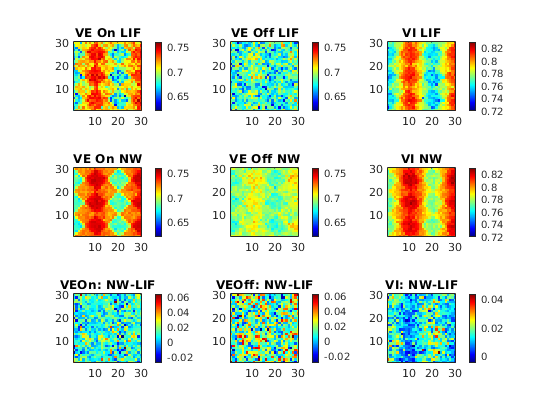

VERange = [0.62 0.76];
VIRange = [0.72 0.83];

figure
subplot 331
ShowField(mVEOnLIF, 1:900, 30, 30)
title('VE On LIF')
caxis(VERange)
subplot 332
ShowField(mVEOffLIF, 1:900, 30, 30)
title('VE Off LIF')
caxis(VERange)
subplot 333
ShowField(mVILIF, 1:900, 30, 30)
title('VI LIF')
caxis(VIRange)
subplot 334
ShowField(mVEOnPixVec, 1:900, 30, 30)
title('VE On NW')
caxis(VERange)
subplot 335
ShowField(mVEOffPixVec , 1:900, 30, 30)
caxis(VERange)
title('VE Off NW')
subplot 336
ShowField(mVIPixVec , 1:900, 30, 30)
caxis(VIRange)
title('VI NW')

subplot 337
ShowField(mVEOnPixVec - mVEOnLIF, 1:900, 30, 30)
title('VEOn: NW-LIF')
subplot 338
ShowField(mVEOffPixVec - mVEOffLIF, 1:900, 30, 30)
title('VEOff: NW-LIF')
subplot 339
ShowField(mVIPixVec - mVILIF, 1:900, 30, 30)
title('VI: NW-LIF')
for ii = 1:9
    subplot(3,3,ii)
    axis square
end

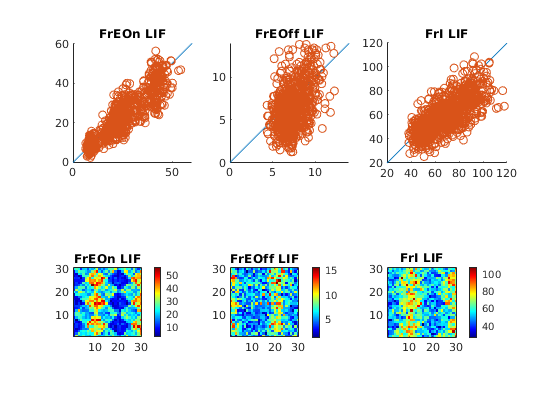


figure
subplot 231
hold on
plot(0:120,0:120)
scatter(FrEOnPixVec, FrEOnLIF)
axis([0 60 0 60])
axis square
title('FrEOn LIF')

subplot 232
hold on
plot(0:120,0:120)
scatter(FrEOffPixVec, FrEOffLIF)
axis([0 14 0 14])
axis square
title('FrEOff LIF')

subplot 233
hold on
plot(0:120,0:120)
scatter(FrIPixVec, FrILIF)
axis([20 120 20 120])
axis square
title('FrI LIF')

subplot 234
ShowField(FrEOnLIF, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOn LIF')

subplot 235
ShowField(FrEOffLIF, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOff LIF')

subplot 236
ShowField(FrILIF, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrI LIF')

FrEOnPixUse  = Fr_MFinv(1:PixNum);
FrEOffPixUse = Fr_MFinv(PixNum+1:2*PixNum);
FrIPixUse = Fr_MFinv(2*PixNum+1:3*PixNum);


mVEOnPixUse  = mVEOnLIF;
mVEOffPixUse = mVEOffLIF;
mVIPixUse = mVILIF;

% Setup preused Firing rates for off E
%FrPreUseDim = find(lambda_EOff_Pixel<0.08) + PixNum;
FrPreUseDim = (1:PixNum) + PixNum;
%FrPreUse = FrEOffPixUse(FrPreUseDim - PixNum); 
%FrPreUse = FrEOffLIF(FrPreUseDim - PixNum); 
FrPreUse = [];

% Mats
MatEE = (S_EE*(1-p_EEFail))*full(C_EE_Pixel_Us); % Need Ref here??
MatEI = S_EI *              full(C_EI_Pixel_Us);
MatIE = S_IE *              full(C_IE_Pixel_Us).*(Ve-repmat(mVIPixUse,1,PixNum));
MatII = S_II *              full(C_II_Pixel_Us).*(Vi-repmat(mVIPixUse,1,PixNum));
ConnMat = [MatEE.*(Ve-repmat(mVEOnPixUse,1,PixNum))/2 , MatEE.*(Ve-repmat(mVEOnPixUse,1,PixNum))/2 , MatEI.*(Vi-repmat(mVEOnPixUse,1,PixNum));
           MatEE.*(Ve-repmat(mVEOffPixUse,1,PixNum))/2, MatEE.*(Ve-repmat(mVEOffPixUse,1,PixNum))/2, MatEI.*(Vi-repmat(mVEOffPixUse,1,PixNum));
           MatIE/2                                    , MatIE/2                                    , MatII];
% Leak On/Off
LeakEOn  = gL_E * (0-mVEOnPixUse)  * 1e3;
LeakEOff = gL_E * (0-mVEOffPixUse) * 1e3;
LeakI =    gL_I * (0-mVIPixUse)    * 1e3;
LeakV = [LeakEOn;LeakEOff;LeakI];
% Ext
ExtEOn  = (lambda_EOn_Pixel*S_Elgn  + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEOnPixUse ) * 1e3;
ExtEOff = (lambda_EOff_Pixel*S_Elgn + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEOffPixUse) * 1e3;
ExtI =    (lambda_I_Pixel*S_Ilgn    + rI_amb*S_amb + L6I_Pixel*S_IL6).*(Ve-mVIPixUse)    * 1e3;
ExtV = [ExtEOn;ExtEOff;ExtI];
% Ref Use
RefEOn = 1-FrEOnPixUse*tau_ref/1e3;
RefEOff = 1-FrEOffPixUse*tau_ref/1e3;
RefI = 1-FrIPixUse*tau_ref/1e3;
RefM = diag([RefEOn;RefEOff;RefI]);


% MF Equations:
%Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
tic
    if isempty(FrPreUse)
    Fr_MFinv = (eye(3*PixNum)-RefM*ConnMat) \ (RefM * ( ExtV + LeakV));
    else
        FrPreVec = zeros(PixNum*3,1); FrPreVec(FrPreUseDim) = FrPreUse;
        DimAll = 1:PixNum*3; FrminusDim = DimAll(~ismember(DimAll,FrPreUse));
        FrPreReplace = RefM*ConnMat * FrPreVec; 
        % Now compute in the subspace
        FrPreMinus = FrPreReplace(FrminusDim);
        RefMMinus  = RefM(FrminusDim, FrminusDim);
        ConnMatMinus = ConnMat(FrminusDim, FrminusDim);
        ExtVMinus = ExtV(FrminusDim);
        LeakVMinus = LeakV(FrminusDim);
        Fr_MFinvMinus = (eye(length(FrminusDim))-RefMMinus*ConnMatMinus) \ ...
                        (RefMMinus * ( ExtVMinus + LeakVMinus) + FrPreMinus);
        % make up MF output            
        Fr_MFinv = zeros(PixNum*3,1);   
        Fr_MFinv(FrminusDim) = Fr_MFinvMinus; Fr_MFinv(FrPreUseDim) = FrPreUse; 
    end
toc

Elapsed time is 0.120216 seconds.


% Err